close("all"); clear; clc;

ts = 0.1;
tf = 20;
ns = tf/ts;
s = linspace(0,tf,ns + 1);

vx = 80/3.6;
k = 0;
C = bikeSimToSharp(bigSportsParameters());
sys = sharpMotorcycleRoadRelative(C,vx);

x0 = [
    0;
    zeros(9,1)
    ];

xmax = [
    3.5;
    deg2rad(90);
    deg2rad(60);
    deg2rad(90);
    5;
    pi;
    pi;
    2*pi;
    1E01;
    1E01
    ];

umax = 50;

params.tFinal = tf;
params.R0 = zonotope(interval(x0,x0));
params.u = zeros(2,tf/ts + 1);
params.U = zonotope(interval([-umax;0],[umax;0]));

options.timeStep = ts;
options.zonotopeOrder = 20;
options.taylorTerms = 10;

R = project(reach(sys,params,options),1:2);
z = R.timePoint.set.';
v = cellfun(@vertices,z,"uniform",0);
fp = @(s,v)[0.*v(1,:) + s;v(1,:);0.*v(1,:)];
C = cellfun(fp,num2cell(s),v,"uniform",0);

% Rz = @(a)rotz(rad2deg(a));
% Rx = @(a)rotx(rad2deg(a));
% fg = @(c,v)c + Rz(v(2))*Rx(v(3))*[0;0;1];
% n2c = @(x)num2cell(x,1);
% fG = @(c,v)cell2mat(cellfun(fg,n2c(c),n2c(v),"uniform",0));
% G = cellfun(fG,C,v,"uniform",0);

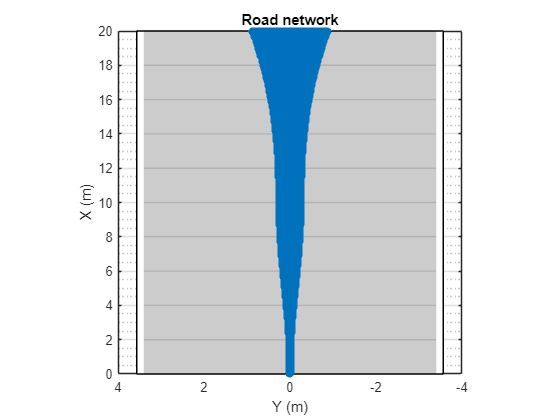

pC = cell2mat(C);
% pG = cell2mat(G);

rd = Road();
rd.addStraight(tf);
plot(rd);
axe = gca;
hold(axe,"on");
scatter(axe,pC(1,:),pC(2,:),"filled");
% scatter3(axe,pG(1,:),pG(2,:),pG(3,:),"filled");
hold(axe,"off");
box(axe,"on");
daspect(axe,[2.5,1,1])

% view(axe,3);